addpath('C:\Users\LENOVO\OneDrive\Desktop\Materi Kuliah\Semester 7\Teknik Neurofuzi\Tugas\Deep Learning Project\Program Files\VGG19');
unzip('Testing.zip');
imds = imageDatastore('Testing','IncludeSubfolders',true,'LabelSource','foldernames');
imdsValidation = imds;

augimdsValidation = augmentedImageDatastore([224 224], imdsValidation);

[YPred,probs] = classify(netTransfer,augimdsValidation);
accuracy = mean(YPred == imdsValidation.Labels)

accuracy = 0.4086

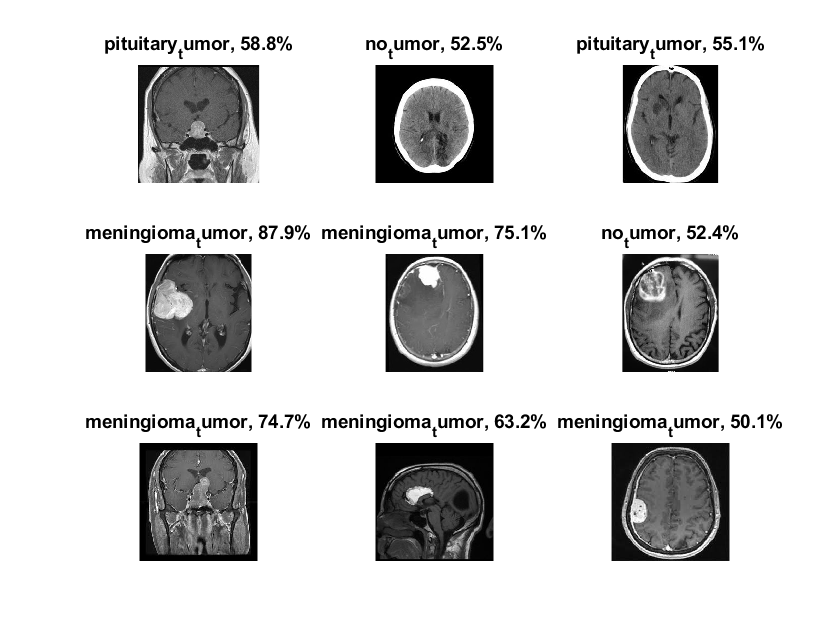


idx = randperm(numel(augimdsValidation.Files),9);
figure
for i = 1:9
    subplot(3,3,i)
    I = readimage(imdsValidation,idx(i));
    imshow(I)
    label = YPred(idx(i));
    title(string(label) + ", " + num2str(100*max(probs(idx(i),:)),3) + "%");
end